# Multi-link pendulum system: Simscape modeling

Input system parameters:

init_angle=90

init_angle = 90

n_links=20

n_links = 20


L=60;       % Length of individual links
W=2;       % Width of links
H=2;       % Depth of links
damping=1;% Damping factor at joints (N*m/(deg/s))
spring=0.1; % Torsional spring constant (N*m/deg)

% Initialising number of links
for i=1:19
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','off');
end

for i=1:(20-n_links)
    set_param(sprintf('pendulum_system/pendulum_links/pendulum_link_%d',i),'commented','through');
end

% set_param('pendulum_system/pendulum_link','commented','through')
simout = sim("pendulum_system.slx");

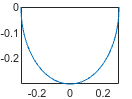

pendulum_angle = simout.pendulum_angle;
end_rotation = simout.end_rotation;

end_x = reshape(simout.end_x(1,1,:),[],1);
end_y = reshape(simout.end_y(1,1,:),[],1);
end_z = reshape(simout.end_z(1,1,:),[],1);

plot(end_x, end_z)